clear
addpath('E:\PhD\Adamantane_data\data')
addpath('E:\PhD\Anaconda2\ANACONDA_2\package\+smita\epicea')
addpath('E:\PhD\meetings_n_conf\2022\wk 14\Colormaps\Colormaps (5)\Colormaps')

S =data_list_adamantane;
epicea_2_scienta=load("epicea_2_scienta_raes.mat");

## import the data if already converted to ANA

for f = 1: length(S)
    raw_data = IO.import_raw(S(f).dir_ada);
    mdata(f) = IO.import_metadata(S(f).dir_ada);
    data            = macro.filter(raw_data, mdata(f)); %define the multiplicity of events
    data_corrected = macro.correct(data, mdata(f));
    data_converted(f) = macro.convert(data_corrected, mdata(f));
    [data_stats(f)] =get_data_stats(data_converted(f));
    hv{f} = (S(f).label);
end

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: the convert macro called angle_p_corr_C2 failed to run on det2


The Scaling factor is 0.54513


Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2
Log: Lens abberation correction performed on det2


Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: the convert macro called angle_p_corr_C2 failed to run on det2


The Scaling factor is 0.48224


## Plot AES

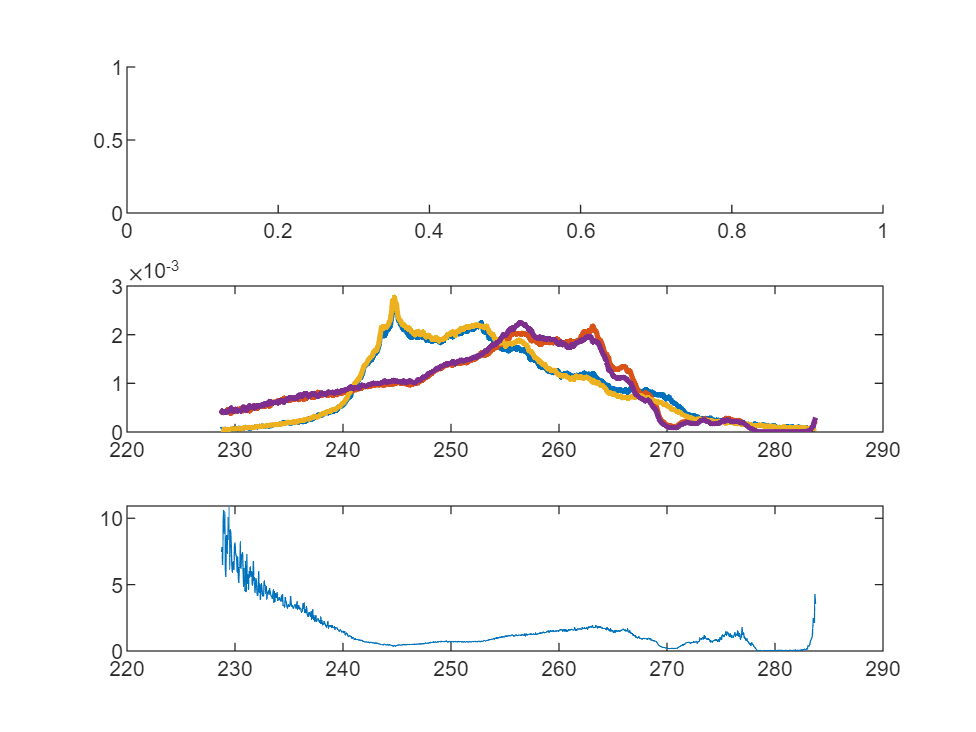

figure; subplot(3,1,1); hold on
for i=1: length(S)
    [centres, electron_KE] = get_AES(data_converted(i), data_stats(i),epicea_2_scienta);
end

% legend(hv); box on
% es_range1 = [241.3;246.3]; %P1 
% es_range2 = [246.8;253.6]; %P2
% es_range3 = [253.8;258.3]; %P3 
% es_range4 = [258.8;265.3]; %P4
% es_range5 = [265.8;270]; %P5 
% es_range6 = [270.2;279.8]; %P6
% yl= ylim;
% patch([es_range1(1),es_range1(1),es_range1(2),es_range1(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.4940 0.1840 0.5560])
% patch([es_range2(1),es_range2(1),es_range2(2),es_range2(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.9290 0.6940 0.1250])
% patch([es_range3(1),es_range3(1),es_range3(2),es_range3(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.4940 0.1840 0.5560])
% patch([es_range4(1),es_range4(1),es_range4(2),es_range4(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.9290 0.6940 0.1250])
% patch([es_range5(1),es_range5(1),es_range5(2),es_range5(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.9290 0.6940 0.1250])
% patch([es_range6(1),es_range6(1),es_range6(2),es_range6(2)],[yl(1),yl(2),yl(2),yl(1)],[0.5 0.5 0.5],'FaceAlpha',0.2,'FaceColor',[0.9290 0.6940 0.1250])

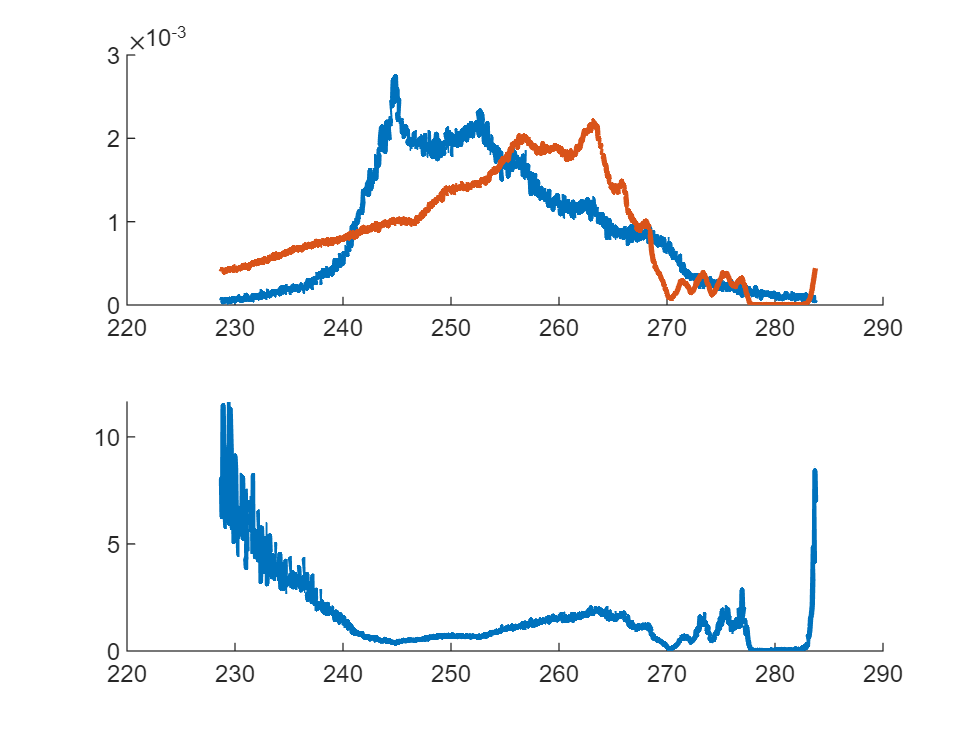

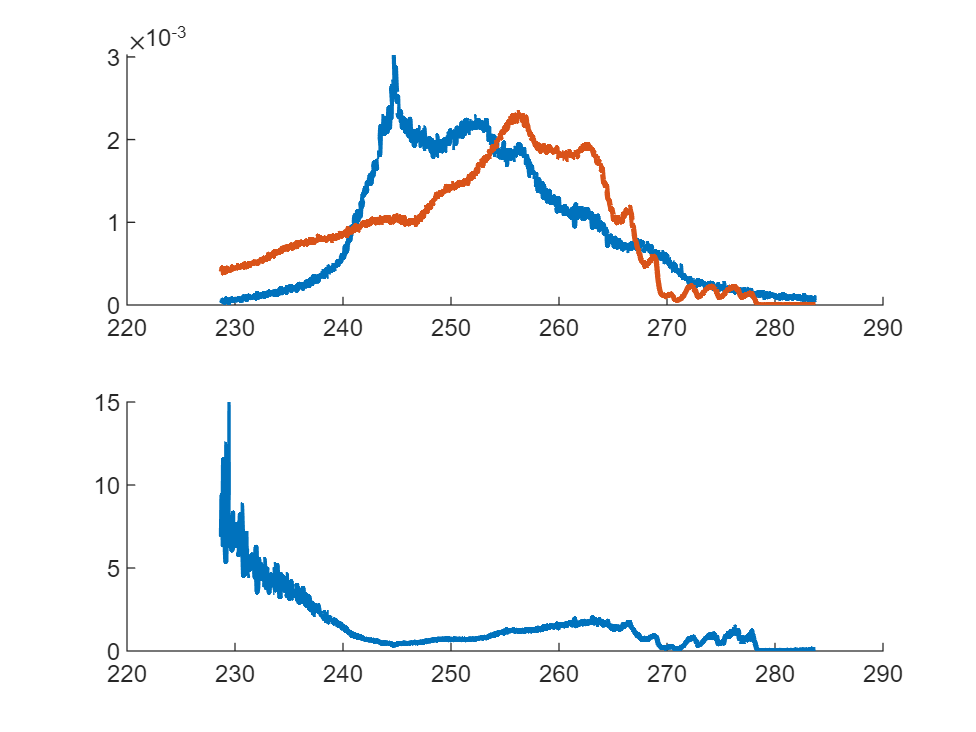

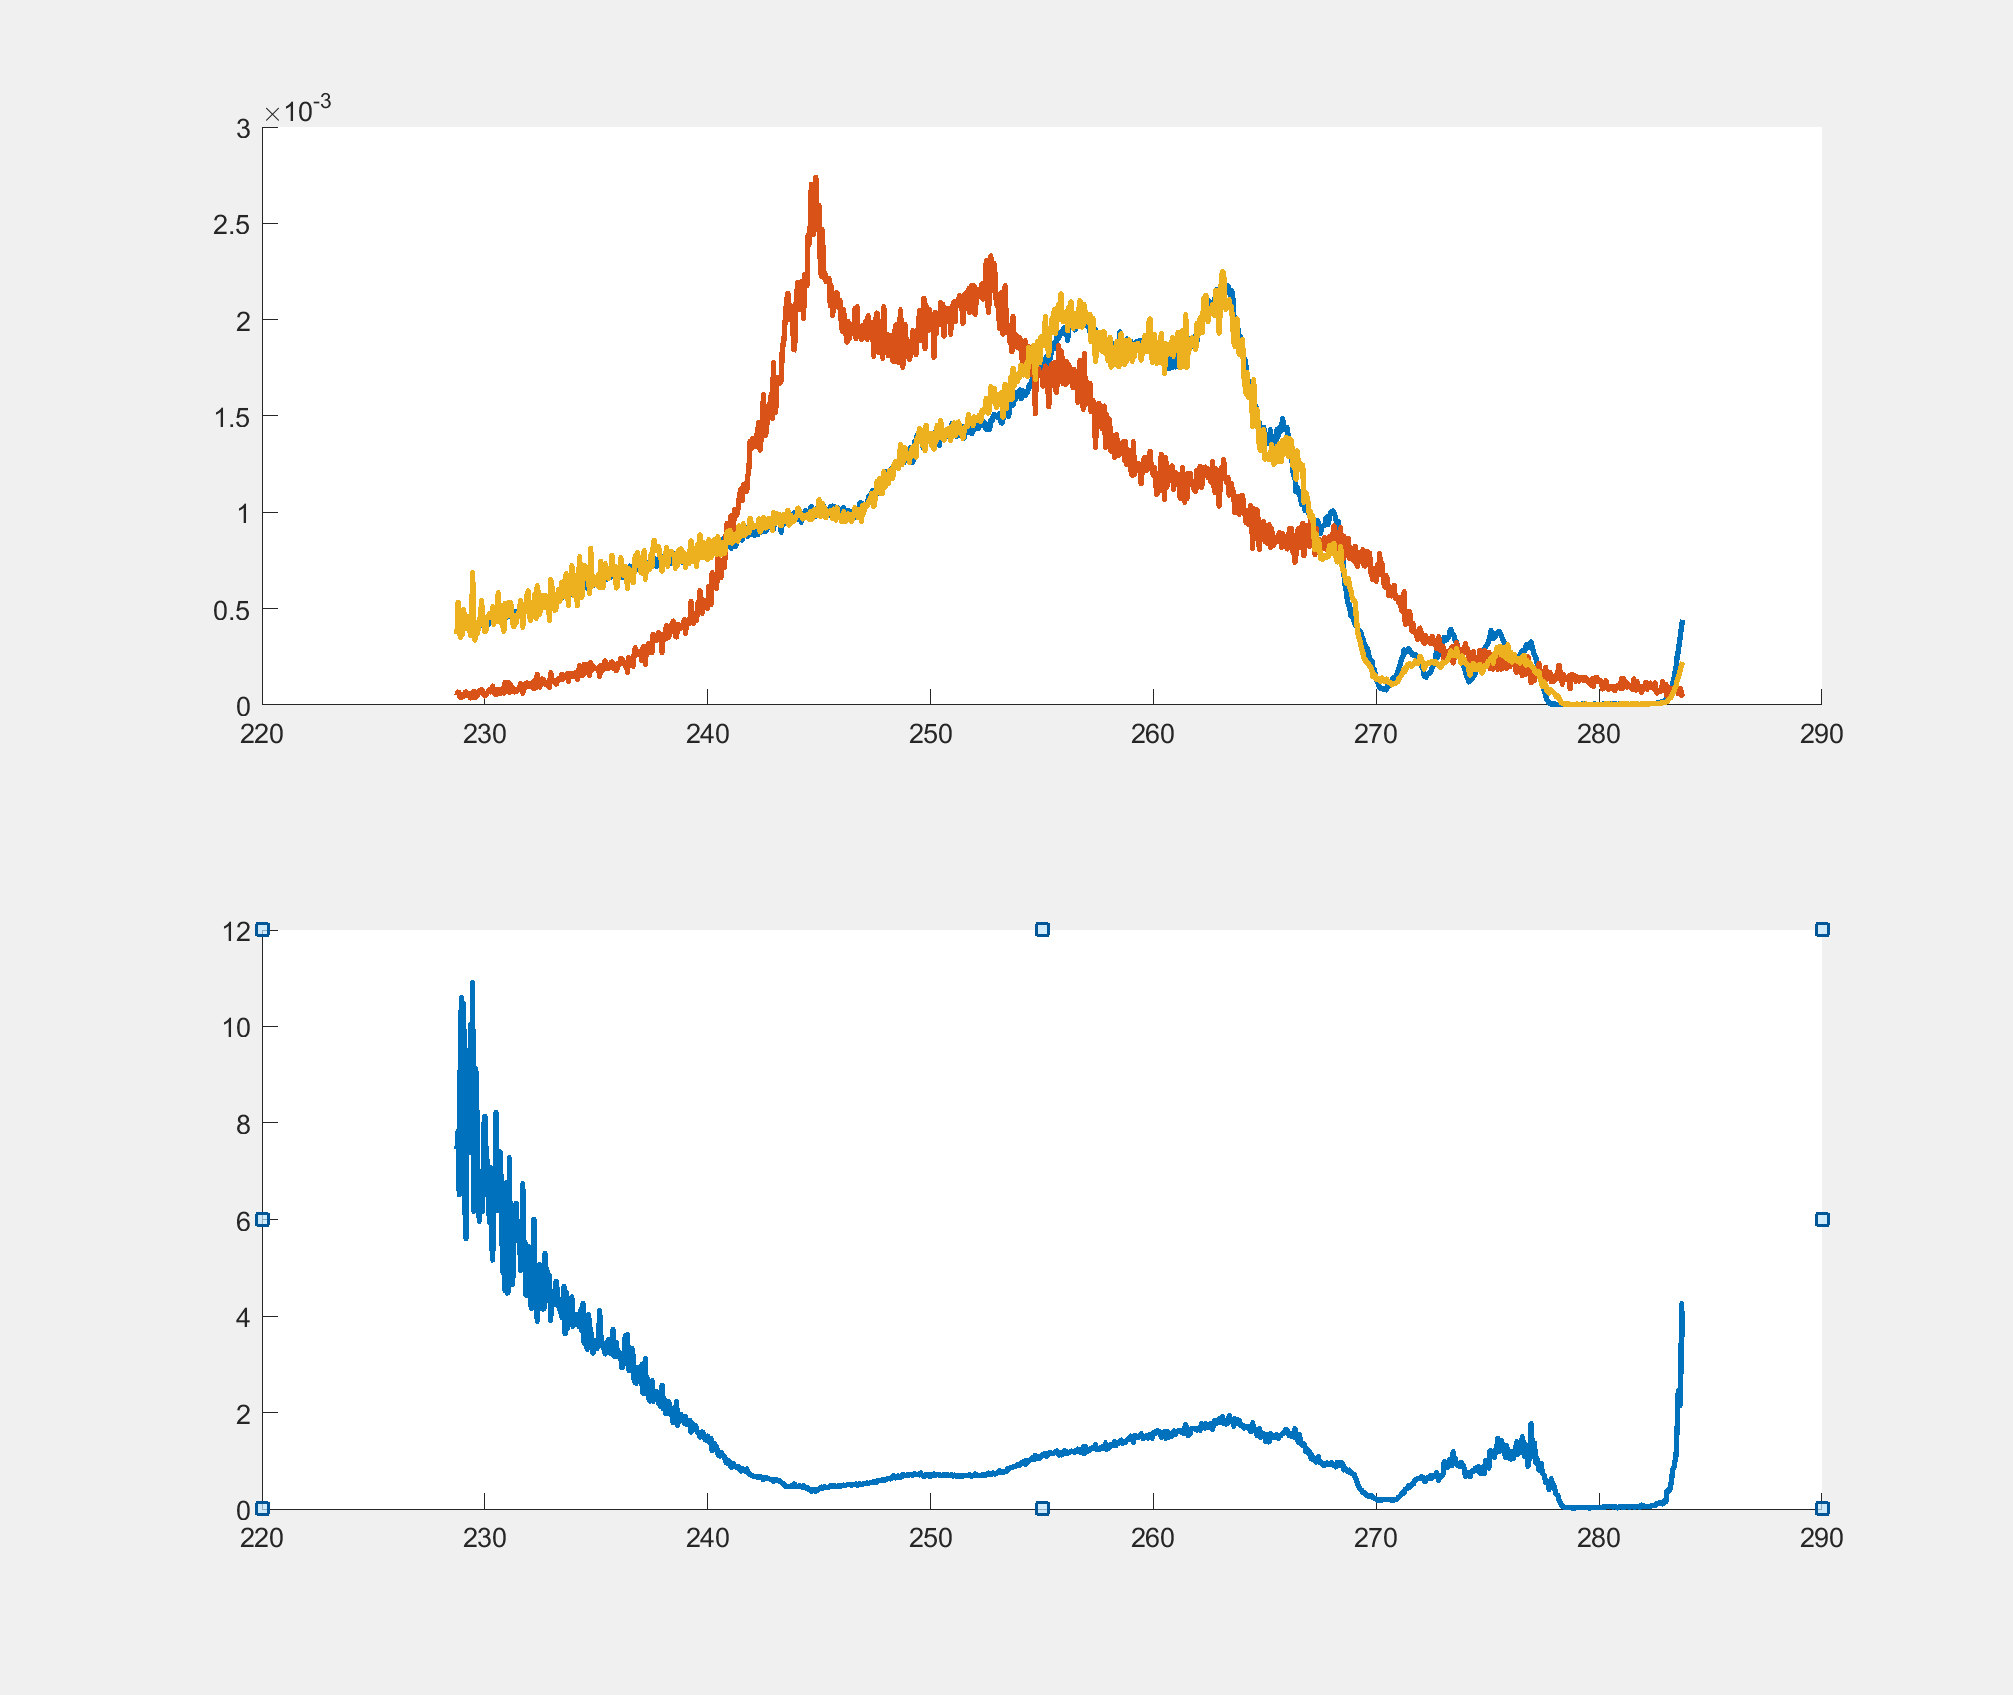

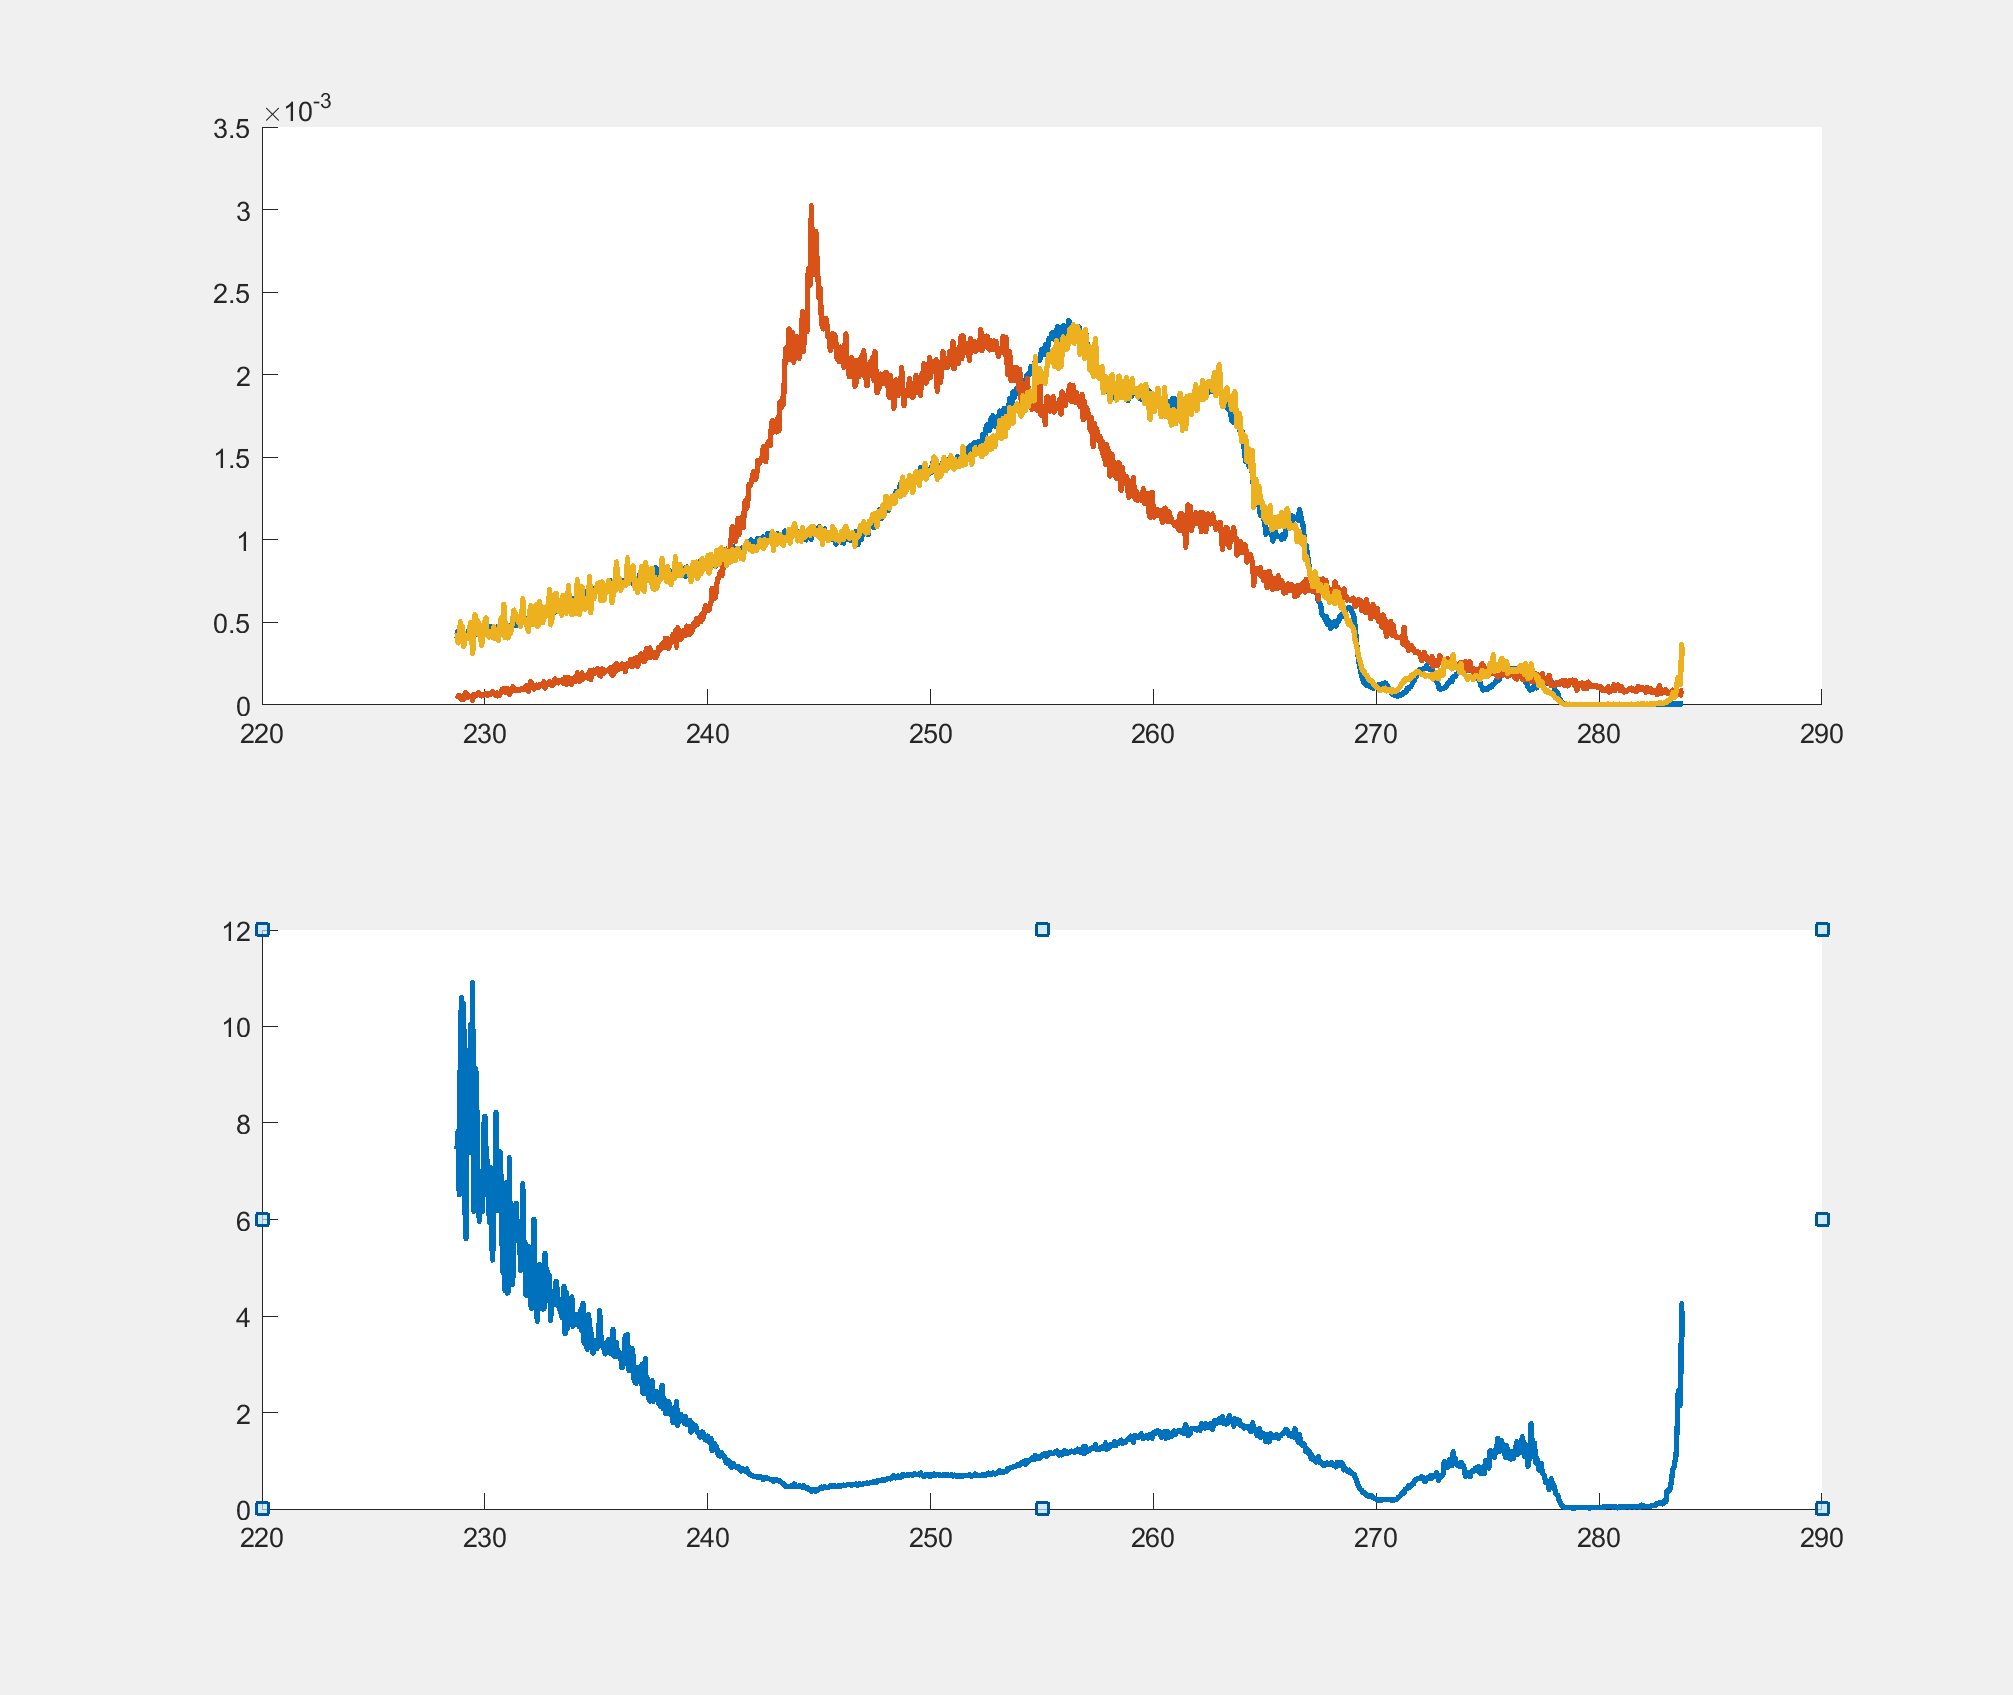

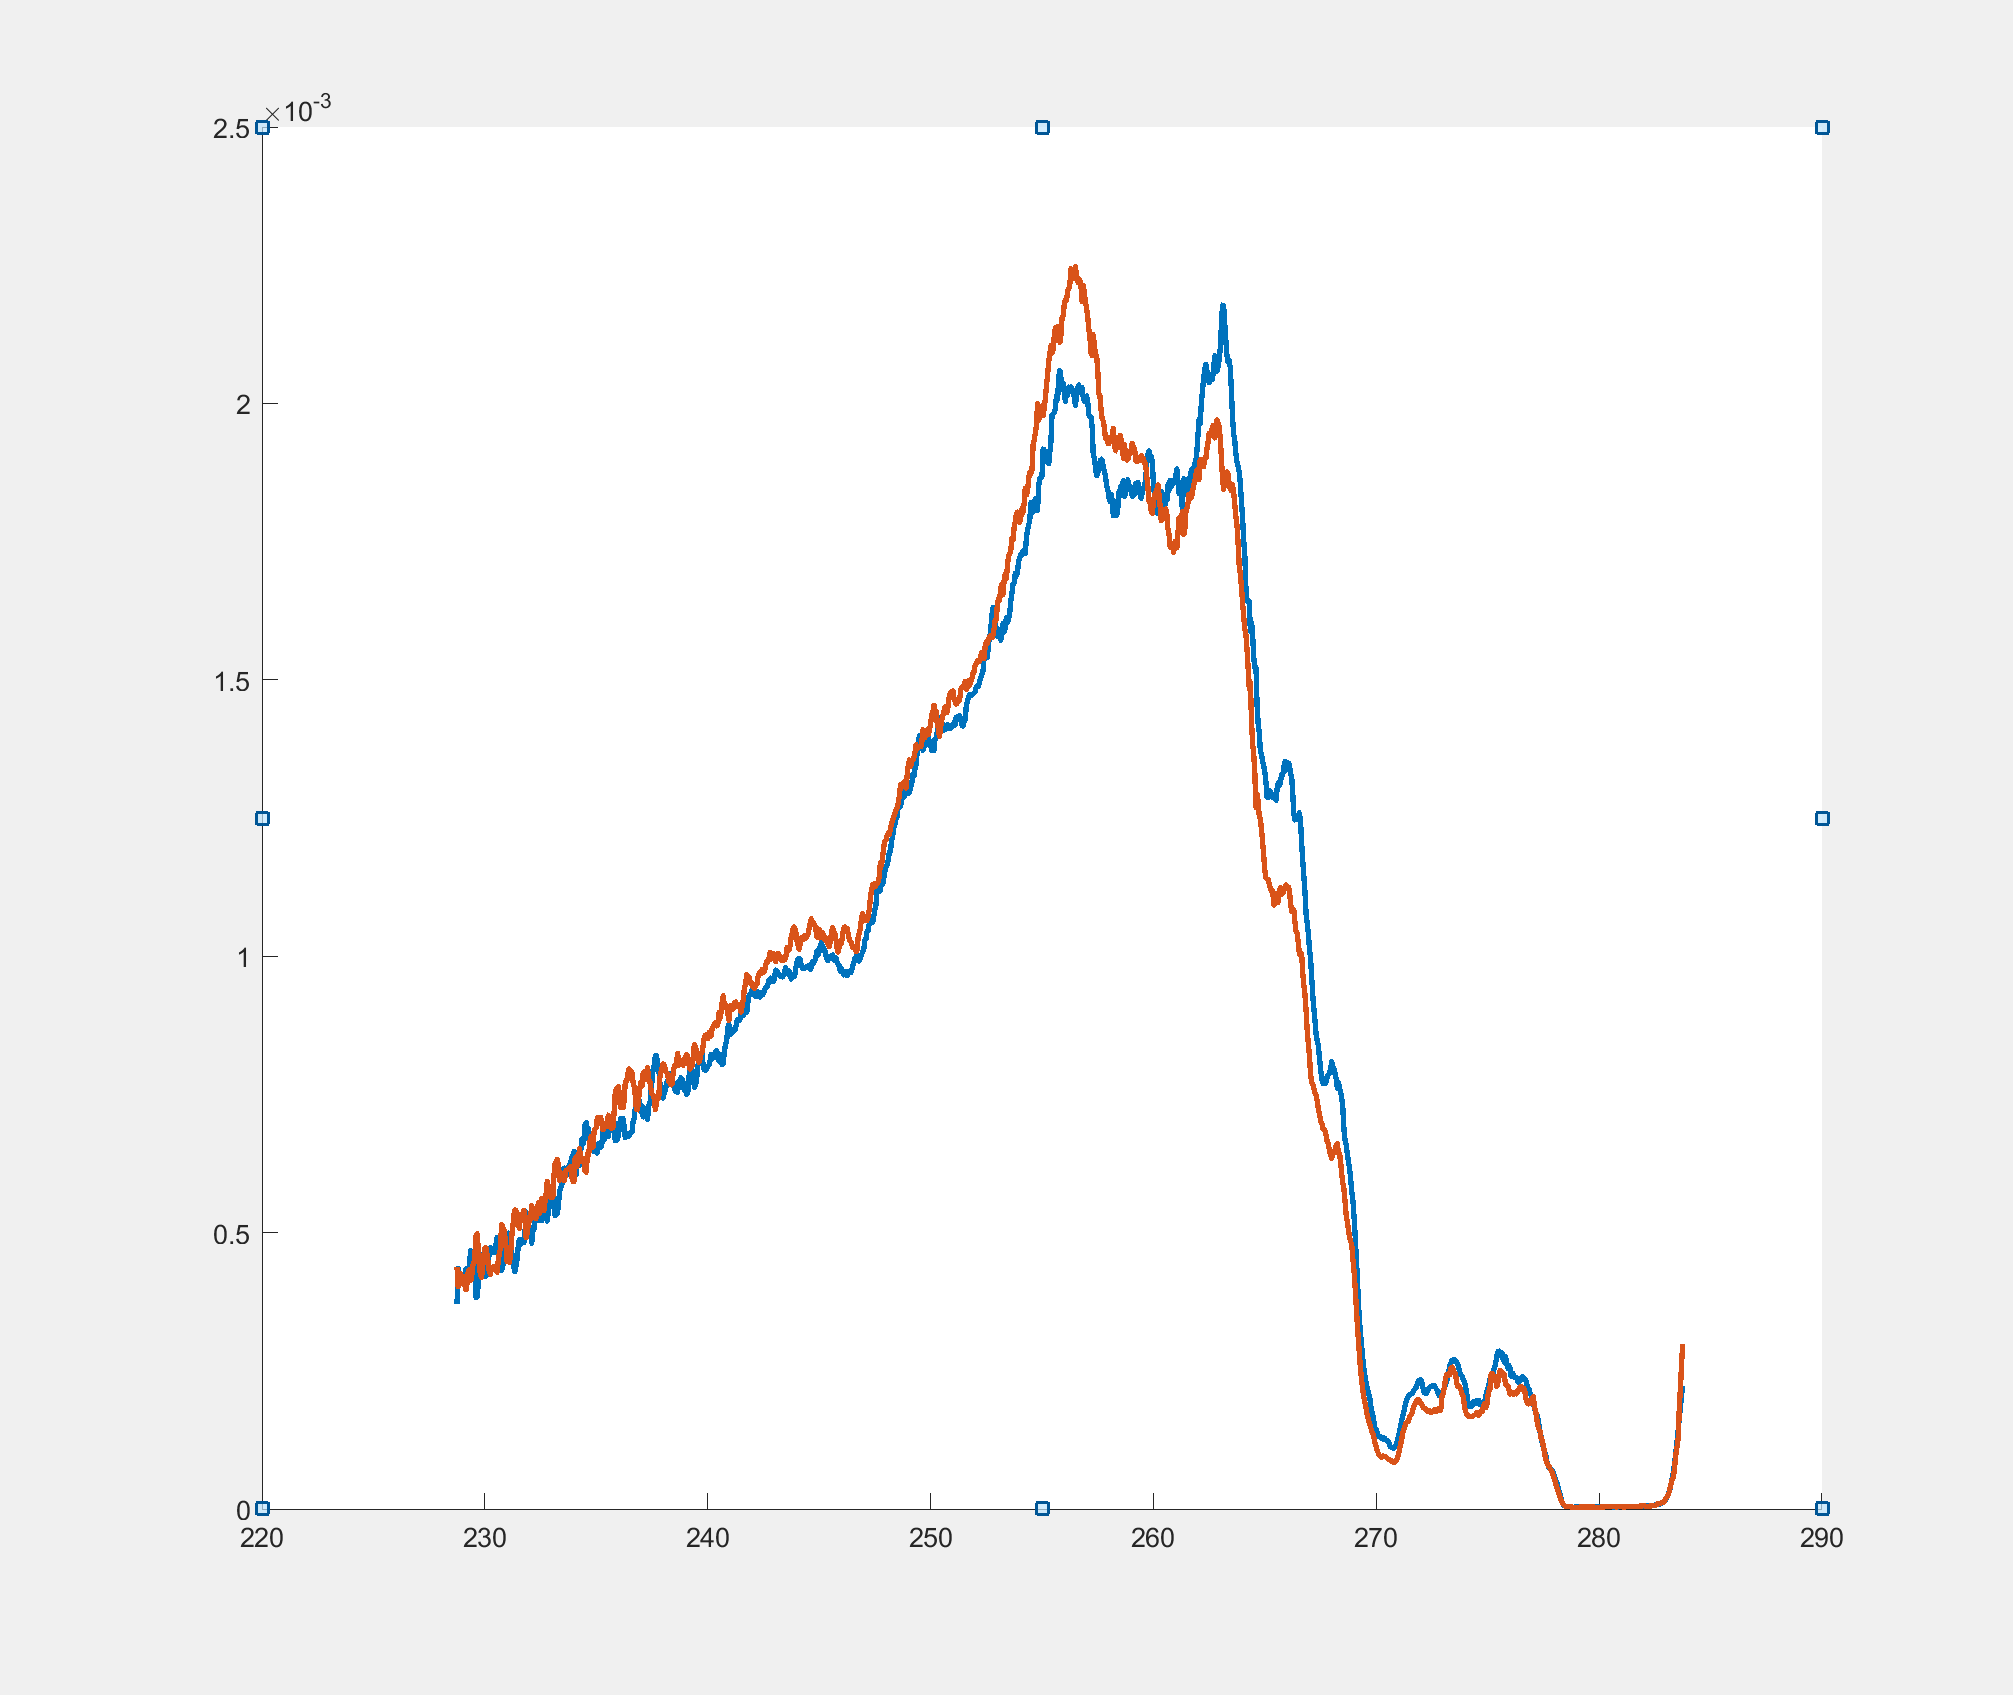

[centres,trans_function] = get_transmission_function(data_converted, data_stats);

## Ion TOF

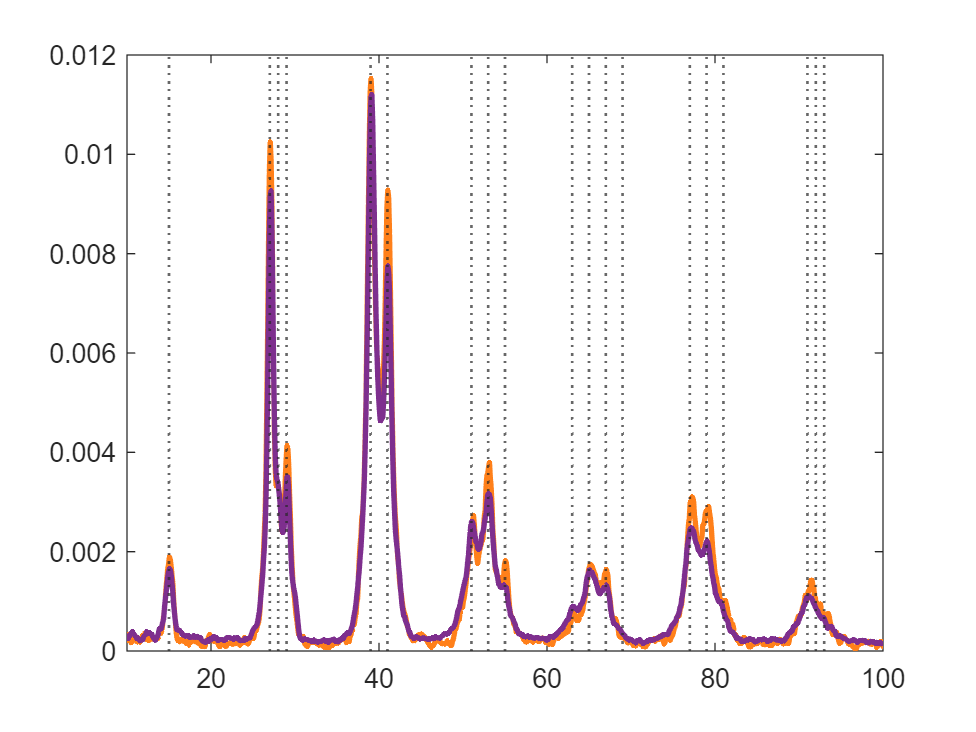

figure; hold on;
for i=1: length(S)
    plot_ion_m2q(data_converted(i), data_stats(i),S(i));
end
m2q_val=[15; 12*2+[3;4;5]; 12*3+[3;5]; 12*4+[3;5;7];12*5+[3;5;7;9];12*6+[5;7;9];12*7+[7;8;9] ];
for xx=1:length(m2q_val)
    xline(m2q_val(xx),':','LineWidth',1);
end
xlim([10 100])
box on

xlabel('Ion mass-to-charge ratio (a.u.)')
ylabel('Normalised intensity')

## Ion Coincidence Branching ratios

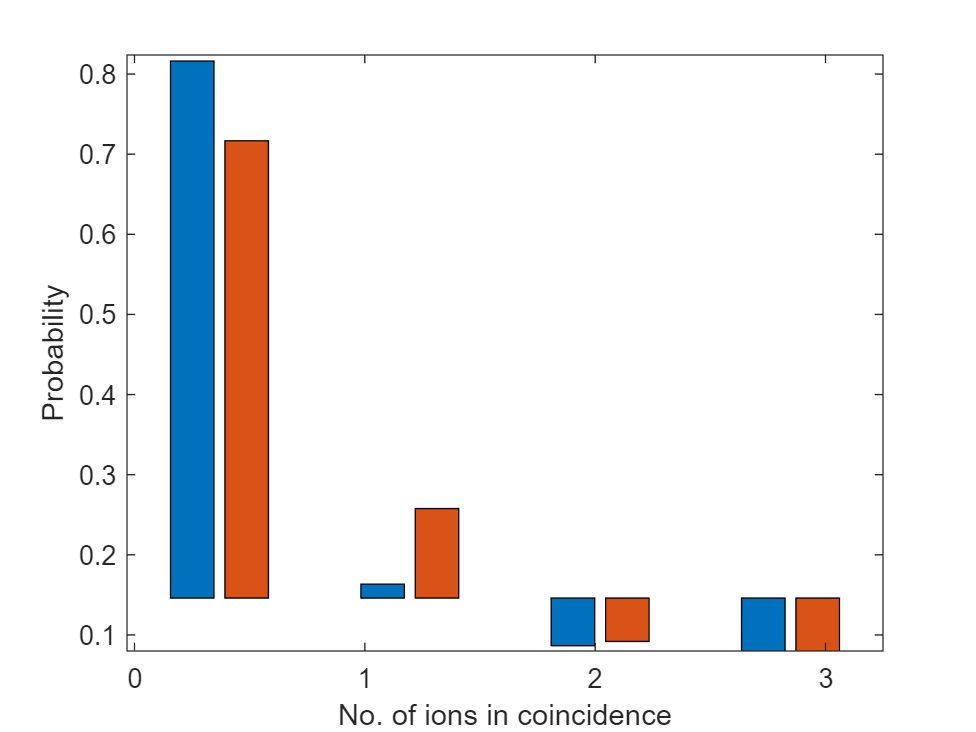

y = [data_stats(1).TP_0, data_stats(2).TP_0;
    data_stats(1).TP_1, data_stats(2).TP_1;
    data_stats(1).TP_2, data_stats(2).TP_2;
    data_stats(1).TP_3, data_stats(2).TP_3;];
figure; bar([0,1,2,3],y)
xlabel('No. of ions in coincidence')
ylabel('Probability')

## Get ROI

c1 = 7;  h1 =9; 
m2q_1 = 12*c1+h1;
filename= sprintf('c%ih%i',c1,h1);%'c%i_c%i',c1,c2);

figure
dire= 'E:\PhD\meetings_n_conf\2022\wk 42\roi_reso_c1_new\'

dire = 'E:\PhD\meetings_n_conf\2022\wk 42\roi_reso_c1_new\'

% m2q_range = get_m2q_range(data_converted(1), data_stats(1),m2q_1)
% save([dire,filename],'m2q_range')

## PEPICO

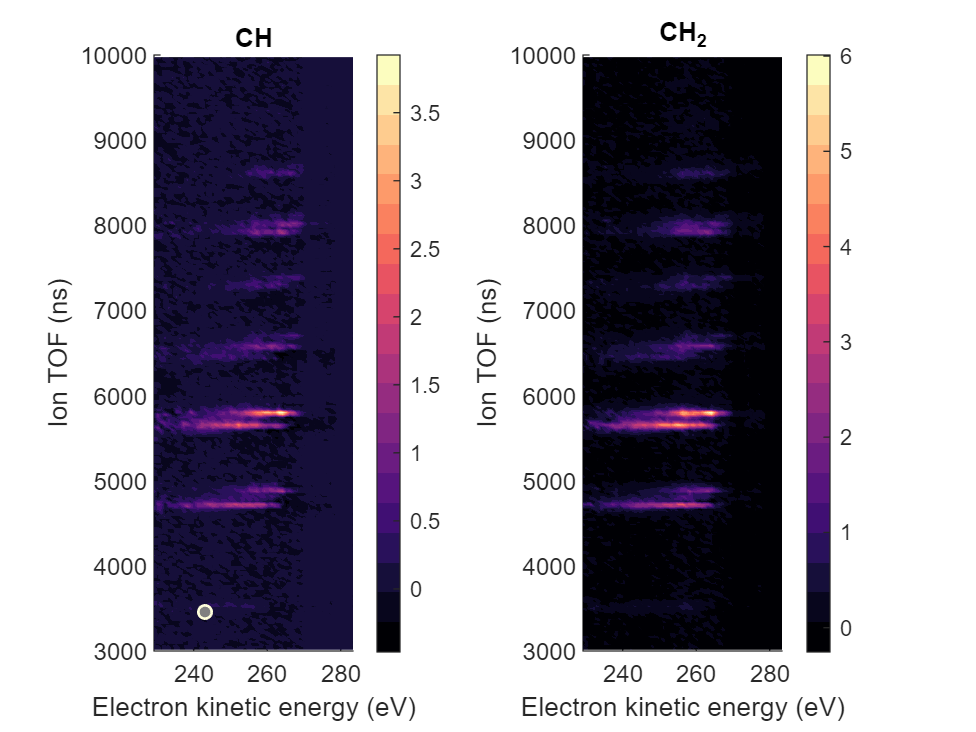

tof_range =[3000 ; 4000];
 tof_range =[3000 ; 10000];
figure%(11);
C1=1; H1=3; H2=5; H3 =7;
m2q_1 = 12*C1+1*H1; m2q_2 = 12*C1+1*H2;  m2q_3 = 12*C1+1*H3; 
label1 =sprintf('C_%dH_{%d}^+', C1,H1);label2 =sprintf('C_%dH_{%d}^+', C1,H2); label3 =sprintf('C_%dH_{%d}^+', C1,H3);

for i=1:length(S)
    subplot(1,length(S),i)
    tof1 = convert.m2q_2_TOF(m2q_1,mdata(i).conv.det2.m2q.factor,mdata(i).conv.det2.m2q.t0);
    tof2 = convert.m2q_2_TOF(m2q_2,mdata(i).conv.det2.m2q.factor,mdata(i).conv.det2.m2q.t0);
    tof3 = convert.m2q_2_TOF(m2q_3,mdata(i).conv.det2.m2q.factor,mdata(i).conv.det2.m2q.t0);
     [TetEI_x_tof,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),tof_range,epicea_2_scienta);
%      yline(tof1,':w','LineWidth',2); 
%      yline(tof2,':w','LineWidth',2); yline(tof3,':w','LineWidth',2);
    title([hv{i}])
end

## Branching ratios of ions

dire= 'E:\PhD\meetings_n_conf\2022\wk 42\roi_reso_c1_new\';
rois = dir(fullfile(dire,'*.mat'));
figure
for i=1:length(S)
    subplot(length(S),1,i)
    for k = 1:numel(rois)
        filename = dir(fullfile(dire,rois(k).name));
        roi = load([dire,filename.name]); % much better than EVAL and LOAD.s
        [TetEI_x_m2q,Xcenters,Ycenters] = get_pepico_m2q(data_converted(i), data_stats(i),[0 140]);
        idy = find(Ycenters>roi.m2q_range(1) & Ycenters<roi.m2q_range(2));
        counts(k,i) = sum(TetEI_x_m2q(:,idy),'all');
        ll= split(rois(k).name,'.');
        label{k} = ll(1);
    end
    cdata=100*counts./sum(counts);
    heatmap(cdata,'CellLabelFormat','%0.1f');
    ax = gca;
    ax.XData = label;
    cm_magma=magma(20);
    colormap(cm_magma)
    caxis([0 15])
end

## Plot ES specific Ion TOF and m2q

figure; set(gcf,'Visible','on')
% tof_range =[2000 ; 11000];%
m2q_val=[15; 12*2+[3;4;5]; 12*3+[3;5]; 12*4+[3;5;7];12*5+[3;5;7;9];12*6+[5;7;9];12*7+[7;8;9] ];

 m2q_range =[10; 100];
% figure; hold on
% es_range_val{1} = [241.3;246.3]; %P1 
% es_range_val{2} = [246.8;253.6]; %P2
% es_range_val{3} = [253.8;258.3]; %P3 
% es_range_val{4} = [258.8;265.3]; %P4
% es_range_val{5} = [265.8;270]; %P5 
% es_range_val{6} = [270.2;279.8]; %P6
es_range_val={};
% es_range_val{1} = [240;246.7]; %P1 
% es_range_val{2} = [246.8;252.8]; %P2
% es_range_val{3} = [253.0;258.1]; %P3 
es_range_val{1} = [258.2;261.1]; %P4
es_range_val{2} = [261.2;264.8]; %P5 
es_range_val{3} = [264.9;266.9]; %P6
es_range_val{4} = [267.0;270.0]; %P7

plt =1
for j=1:length(es_range_val)
        subplot1 = subplot(length(es_range_val),1,plt); 
    for i=1:length(S)%1:2%%:3
        es_range=es_range_val{j};
    [data_stats_es_filt] =get_data_stats_es_filt(data_converted(i),es_range);
    [TetEI_x_m2q,Xcenters,Ycenters] = get_pepico_m2q(data_converted(i), data_stats_es_filt,m2q_range);
    idx = Xcenters>es_range(1) & Xcenters<es_range(2);
    m2q = sum(TetEI_x_m2q(idx,:));
%     subplot1 = subplot(length(es_range_val),length(S),plt); 

%     subplot1 = subplot(3,1,3); 

    hold on
    plot(Ycenters,smooth(m2q./sum(m2q)), 'DisplayName',[hv{i},sprintf(' P%.0f', j)],'LineWidth',2,'Color',S(i).color)%
    legend
%     ylim([0 1])
%     for cc =1:10
%         xline(12*cc);
%     end

% Uncomment the following line to preserve the X-limits of the axes
% xlim(subplot1,[2000 10000]);
% Uncomment the following line to preserve the Y-limits of the axes
% ylim(subplot1,[0 1]);
box(subplot1,'on');
% Set the remaining axes properties
set(subplot1,'FontSize',15,'XGrid','on','XMinorTick','on','YGrid','on');
% Create legend
legend(subplot1,'show');
% xlabel('m2q (a.u.)')
set(gca,'xtick',[])
set(gca,'xticklabel',[])
xlim(m2q_range)
    box on
    for xx=1:length(m2q_val)
    xline(m2q_val(xx),'LineStyle',':','LineWidth',2,'Color',[0.80,0.80,0.80]);
    end
    end
plt =plt+1;
end
% sgtitle(sprintf('E1 : %.1f eV - %.1f eV', es_range(1),es_range(2)))
% xlabel('tof (ns)')



figure; set(gcf,'Visible','on')

for gg=1:length(S)
    set(gcf,'Position',[1,1,615.5,847.5] )
    subplot(1,2,gg); hold on;
    [labels,C, H, Tet_ev_mean,Tet_ev_std] = get_ion_aes(data_converted(gg), data_stats(gg));

    j=1; 
    
    for i=1:7
        xx=find(C==j);
        hyd{j} = H(xx);
        aes_mean{j} = Tet_ev_mean(xx);
        aes_std{j} = Tet_ev_std(xx);
        plot(hyd{j}, aes_mean{j},'*-','DisplayName',num2str(j),'LineWidth',2)
%         errorbar(hyd{j}, aes_mean{j},aes_std{j}, '*-','LineWidth',2, 'DisplayName',num2str(j))
        j=j+1;
    end
    legend
    ylim([246 264])
    xlabel('No of hydrogens')
    ylabel('Mean Auger electron energy')
    box on
    title(hv{gg})
end

## 1 ION TOF

m2q_range =[10 ; 100];
m2q_val=[15; 12*2+[3;4;5]; 12*3+[3;5]; 12*4+[3;5;7];12*5+[3;5;7;9];12*6+[5;7;9];12*7+[7;8;9] ];
int=[];
figure;  hold on
for i=1:length(S)
    subplot(3,1,i)
     [TetEI_x_tof,Xcenters,Ycenters] = get_pepico_m2q(data_converted(i), data_stats(i),m2q_range);   
    xdata= Ycenters;
    ydata= sum(TetEI_x_tof,1);
    int(i,:) =smooth(ydata./sum(ydata));
    plot(xdata,int(i,:),'DisplayName',hv{i},'Color',S(i).color,'LineWidth',2)
%     legend
    ylim([0 0.015])
    xlim([10 100])
    box on
    for xx=1:length(m2q_val)
    xline(m2q_val(xx),'LineStyle',':','LineWidth',2,'Color',[0.80,0.80,0.80]);
    end
end
subplot(3,1,3)
plot(xdata,smooth(int(1,:)-int(2,:)))
xlim([10 100])

for xx=1:length(m2q_val)
    xline(m2q_val(xx));
end
yline(0)

## Slices of PEPICO

C1=6; H1=3; H2=5; H3 =7;
m2q_1 = 12*C1+1*H1; m2q_2 = 12*C1+1*H2;  m2q_3 = 12*C1+1*H3; 
label1 =sprintf('C_%dH_{%d}^+', C1,H1);label2 =sprintf('C_%dH_{%d}^+', C1,H2); label3 =sprintf('C_%dH_{%d}^+', C1,H3);
dtof=70;
for i=1:length(S)
    tof1 = convert.m2q_2_TOF(m2q_1,mdata(i).conv.det2.m2q.factor,mdata(i).conv.det2.m2q.t0);
    tof2 = convert.m2q_2_TOF(m2q_2,mdata(i).conv.det2.m2q.factor,mdata(i).conv.det2.m2q.t0);
    tof3 = convert.m2q_2_TOF(m2q_3,mdata(i).conv.det2.m2q.factor,mdata(i).conv.det2.m2q.t0);
    figure
    subplot(3,1,1);
    [TetEI_x_tof1,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),[tof1-dtof;tof1+dtof],epicea_2_scienta);
     title(label1)
     subplot(3,1,2);
    [TetEI_x_tof2,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),[tof2-dtof;tof2+dtof ],epicea_2_scienta);
    title(label2)
    subplot(3,1,3);
    [TetEI_x_tof3,Xcenters,Ycenters] = plot_pepico(data_converted(i), data_stats(i),[tof3-dtof;tof3+dtof ],epicea_2_scienta);
    title(label3)
    sgtitle(hv{i})
    y1 =sum(TetEI_x_tof1, 2);
    y2 =sum(TetEI_x_tof2, 2);
    y3 =sum(TetEI_x_tof3, 2);
% tof_centers = Ycenters;%Yedges(1:end-1) + diff(Yedges) / 2; %tof values
    energy_val = Xcenters;%Xedges(1:end-1) + diff(Xedges) / 2;

    figure; subplot(3,1,i); 
    hold on
    title(hv{i})
    
%     scatter(energy_val,y1./max(y1),'DisplayName',label1,'MarkerFaceAlpha', 0.5, 'MarkerFaceColor','r'); hold on
%     scatter(energy_val,y2./max(y2),'DisplayName',label2,'MarkerFaceAlpha', 0.5, 'MarkerFaceColor','k'); hold on
    
%     energy_val1 = imresize(energy_val,0.75);
%     y1 = imresize(y1,0.75);
%     energy_val2 = imresize(energy_val,0.5);
%     y2 = imresize(y2,0.5);
    plot(energy_val,y1./max(y1),'r','DisplayName',label1,'LineWidth', 2); hold on
    plot(energy_val,y2./max(y2),'k','DisplayName',label2,'LineWidth', 2); hold on
    plot(energy_val,y3./max(y3),'b','DisplayName',label3,'LineWidth', 2); 
%     ylim([0 1])
%      plot(energy_val,y1,'DisplayName',label1,'LineWidth', 2); hold on
%      plot(energy_val,y2,'DisplayName',label2,'LineWidth', 2); hold on
%     plot(energy_val,y3,'DisplayName',label3,'LineWidth', 2);  
    
    legend 
    
    
end


## Slices of PEPICO

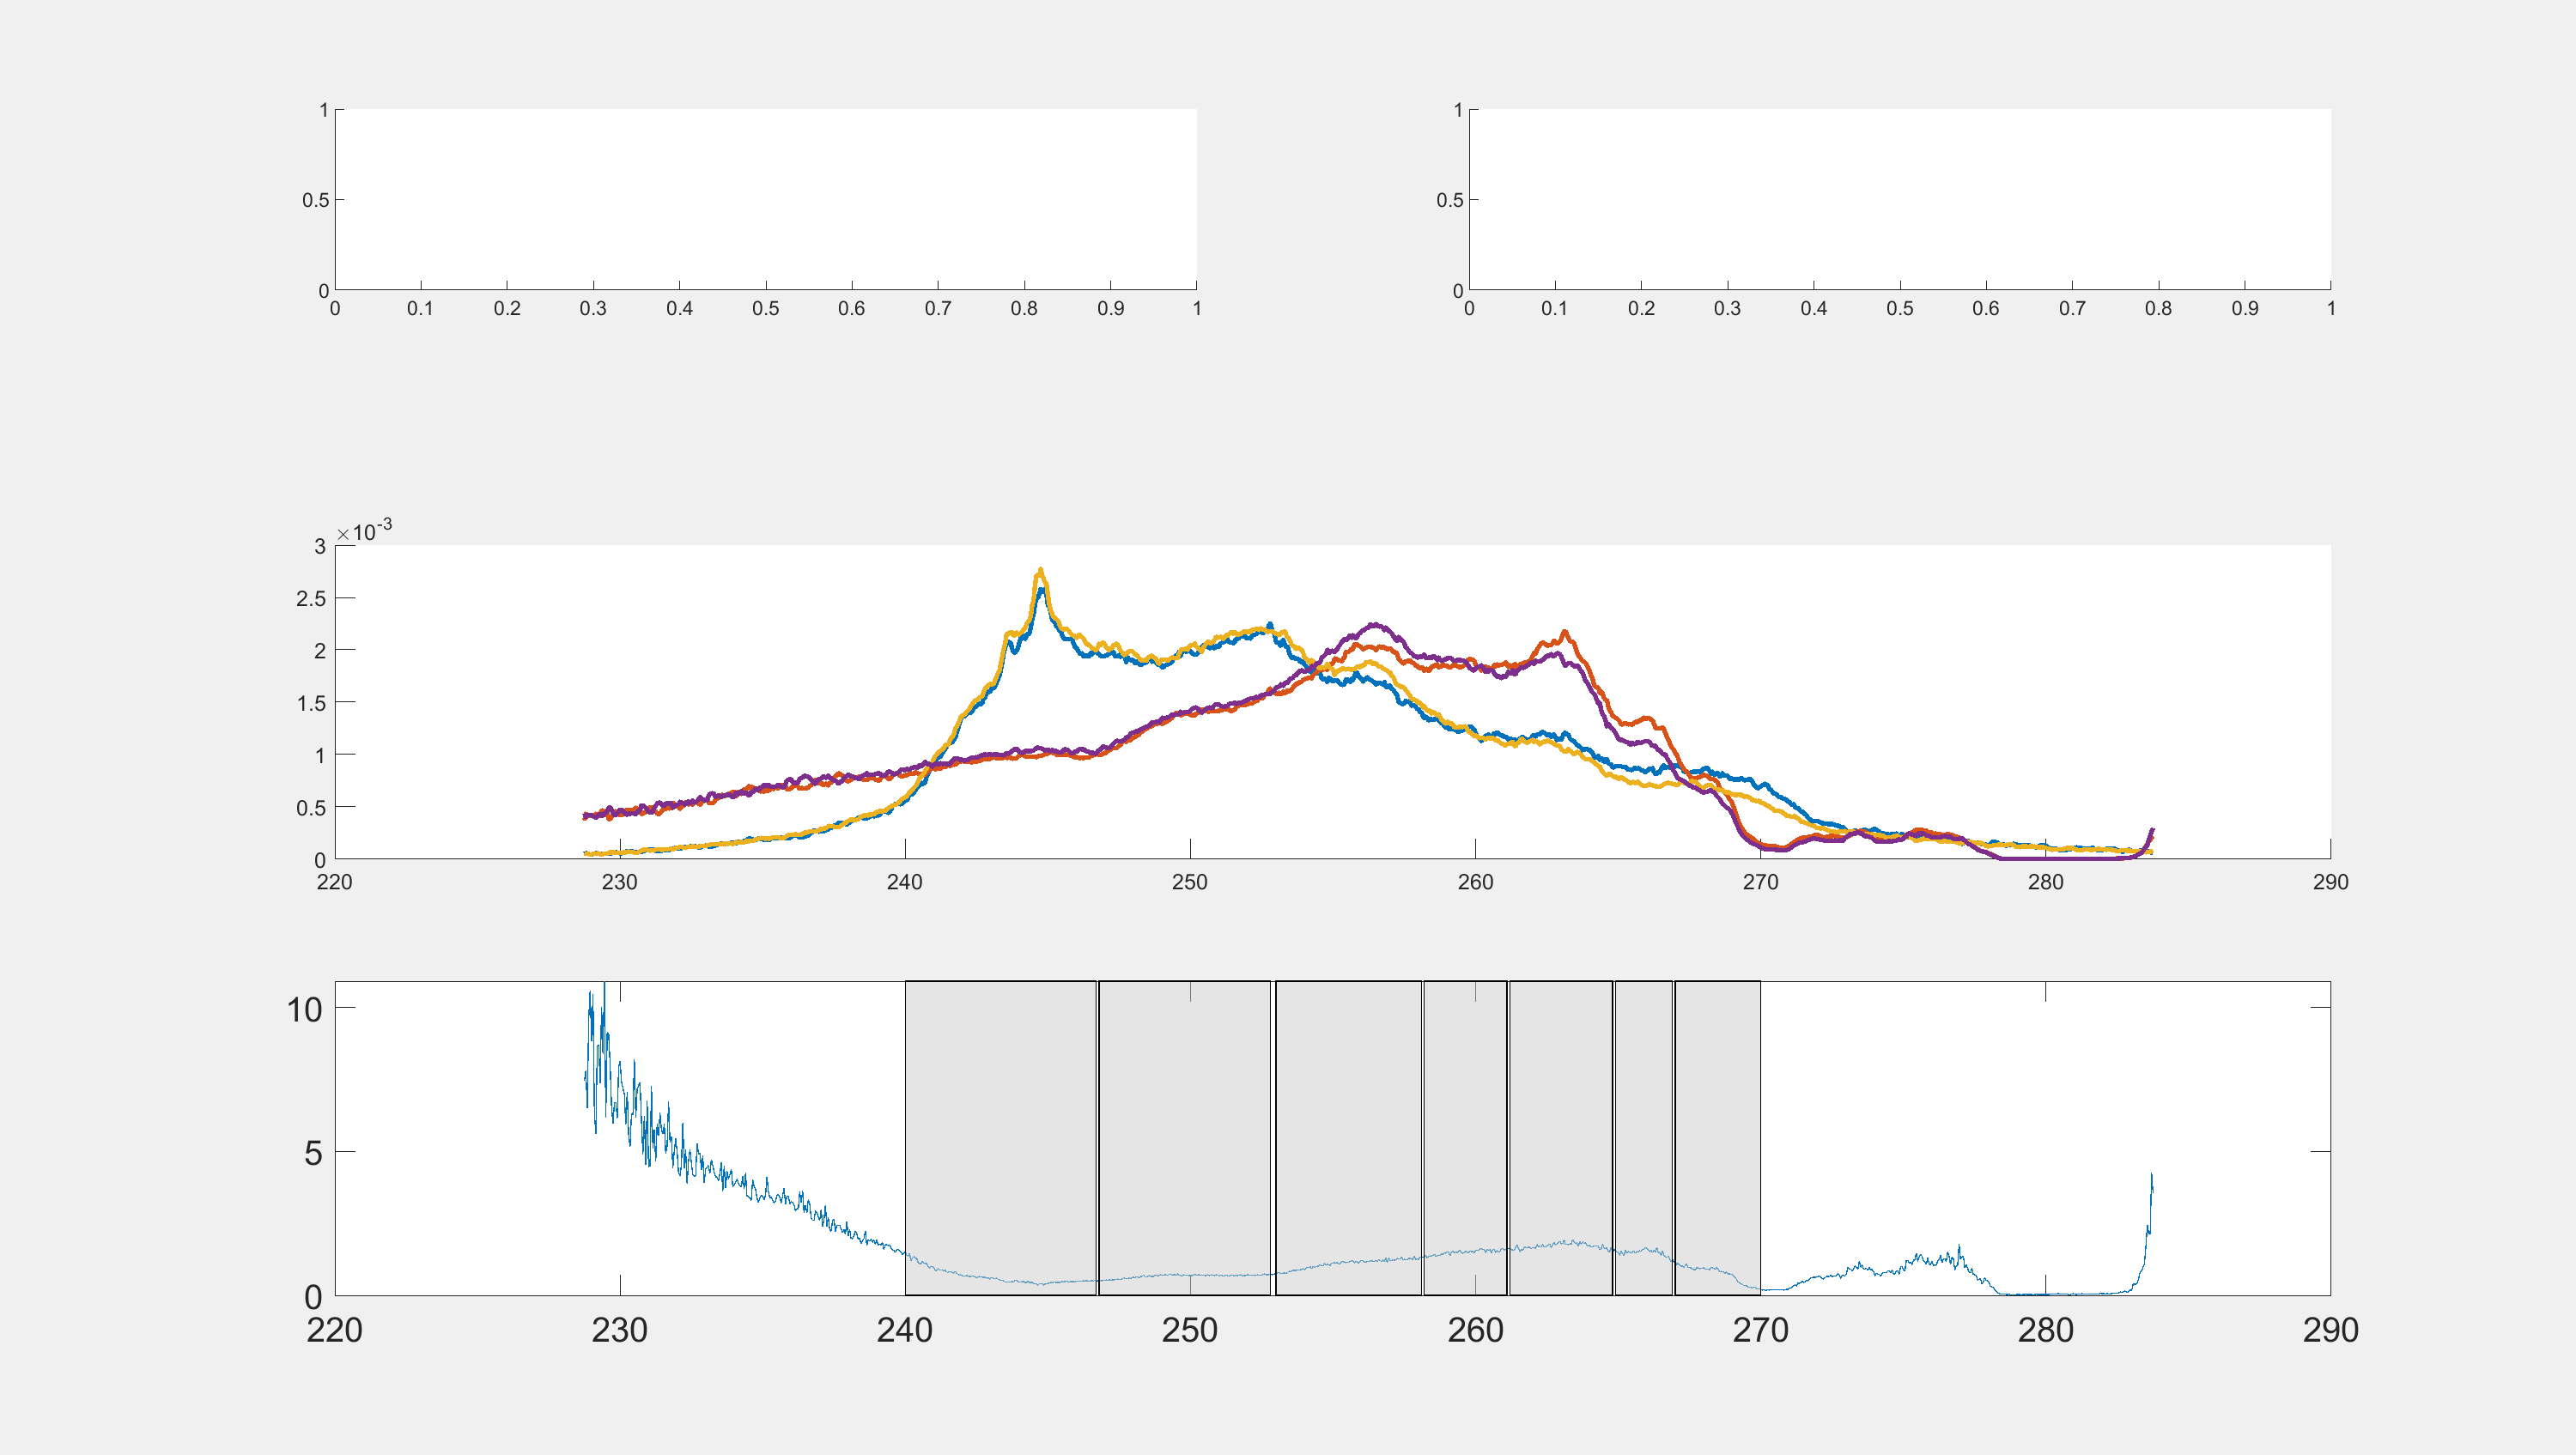

%  m2q_val=[15; 12*2+[3;5]; 12*3+[3;5]; 12*4+[3;5;7];12*5+[5;7;9];12*6+[5;7;9];12*7+[7;9] ];
m2q_val= [12*2+[3;5]; 12*3+[3;5]];%[15; 12*2+[3;5]];%; ]; 
dtof=50; plt=3; %dtof=70

figure; set(gcf,'Visible','on');
subplot(length(m2q_val)+1,length(S),1); 
[centres, electron_KE] = get_AES(data_converted(1), data_stats(1),epicea_2_scienta);
set(gca,'FontSize',15)
make_patch_es
subplot(length(m2q_val)+1,length(S),2); 
[centres, electron_KE] = get_AES(data_converted(2), data_stats(2),epicea_2_scienta);

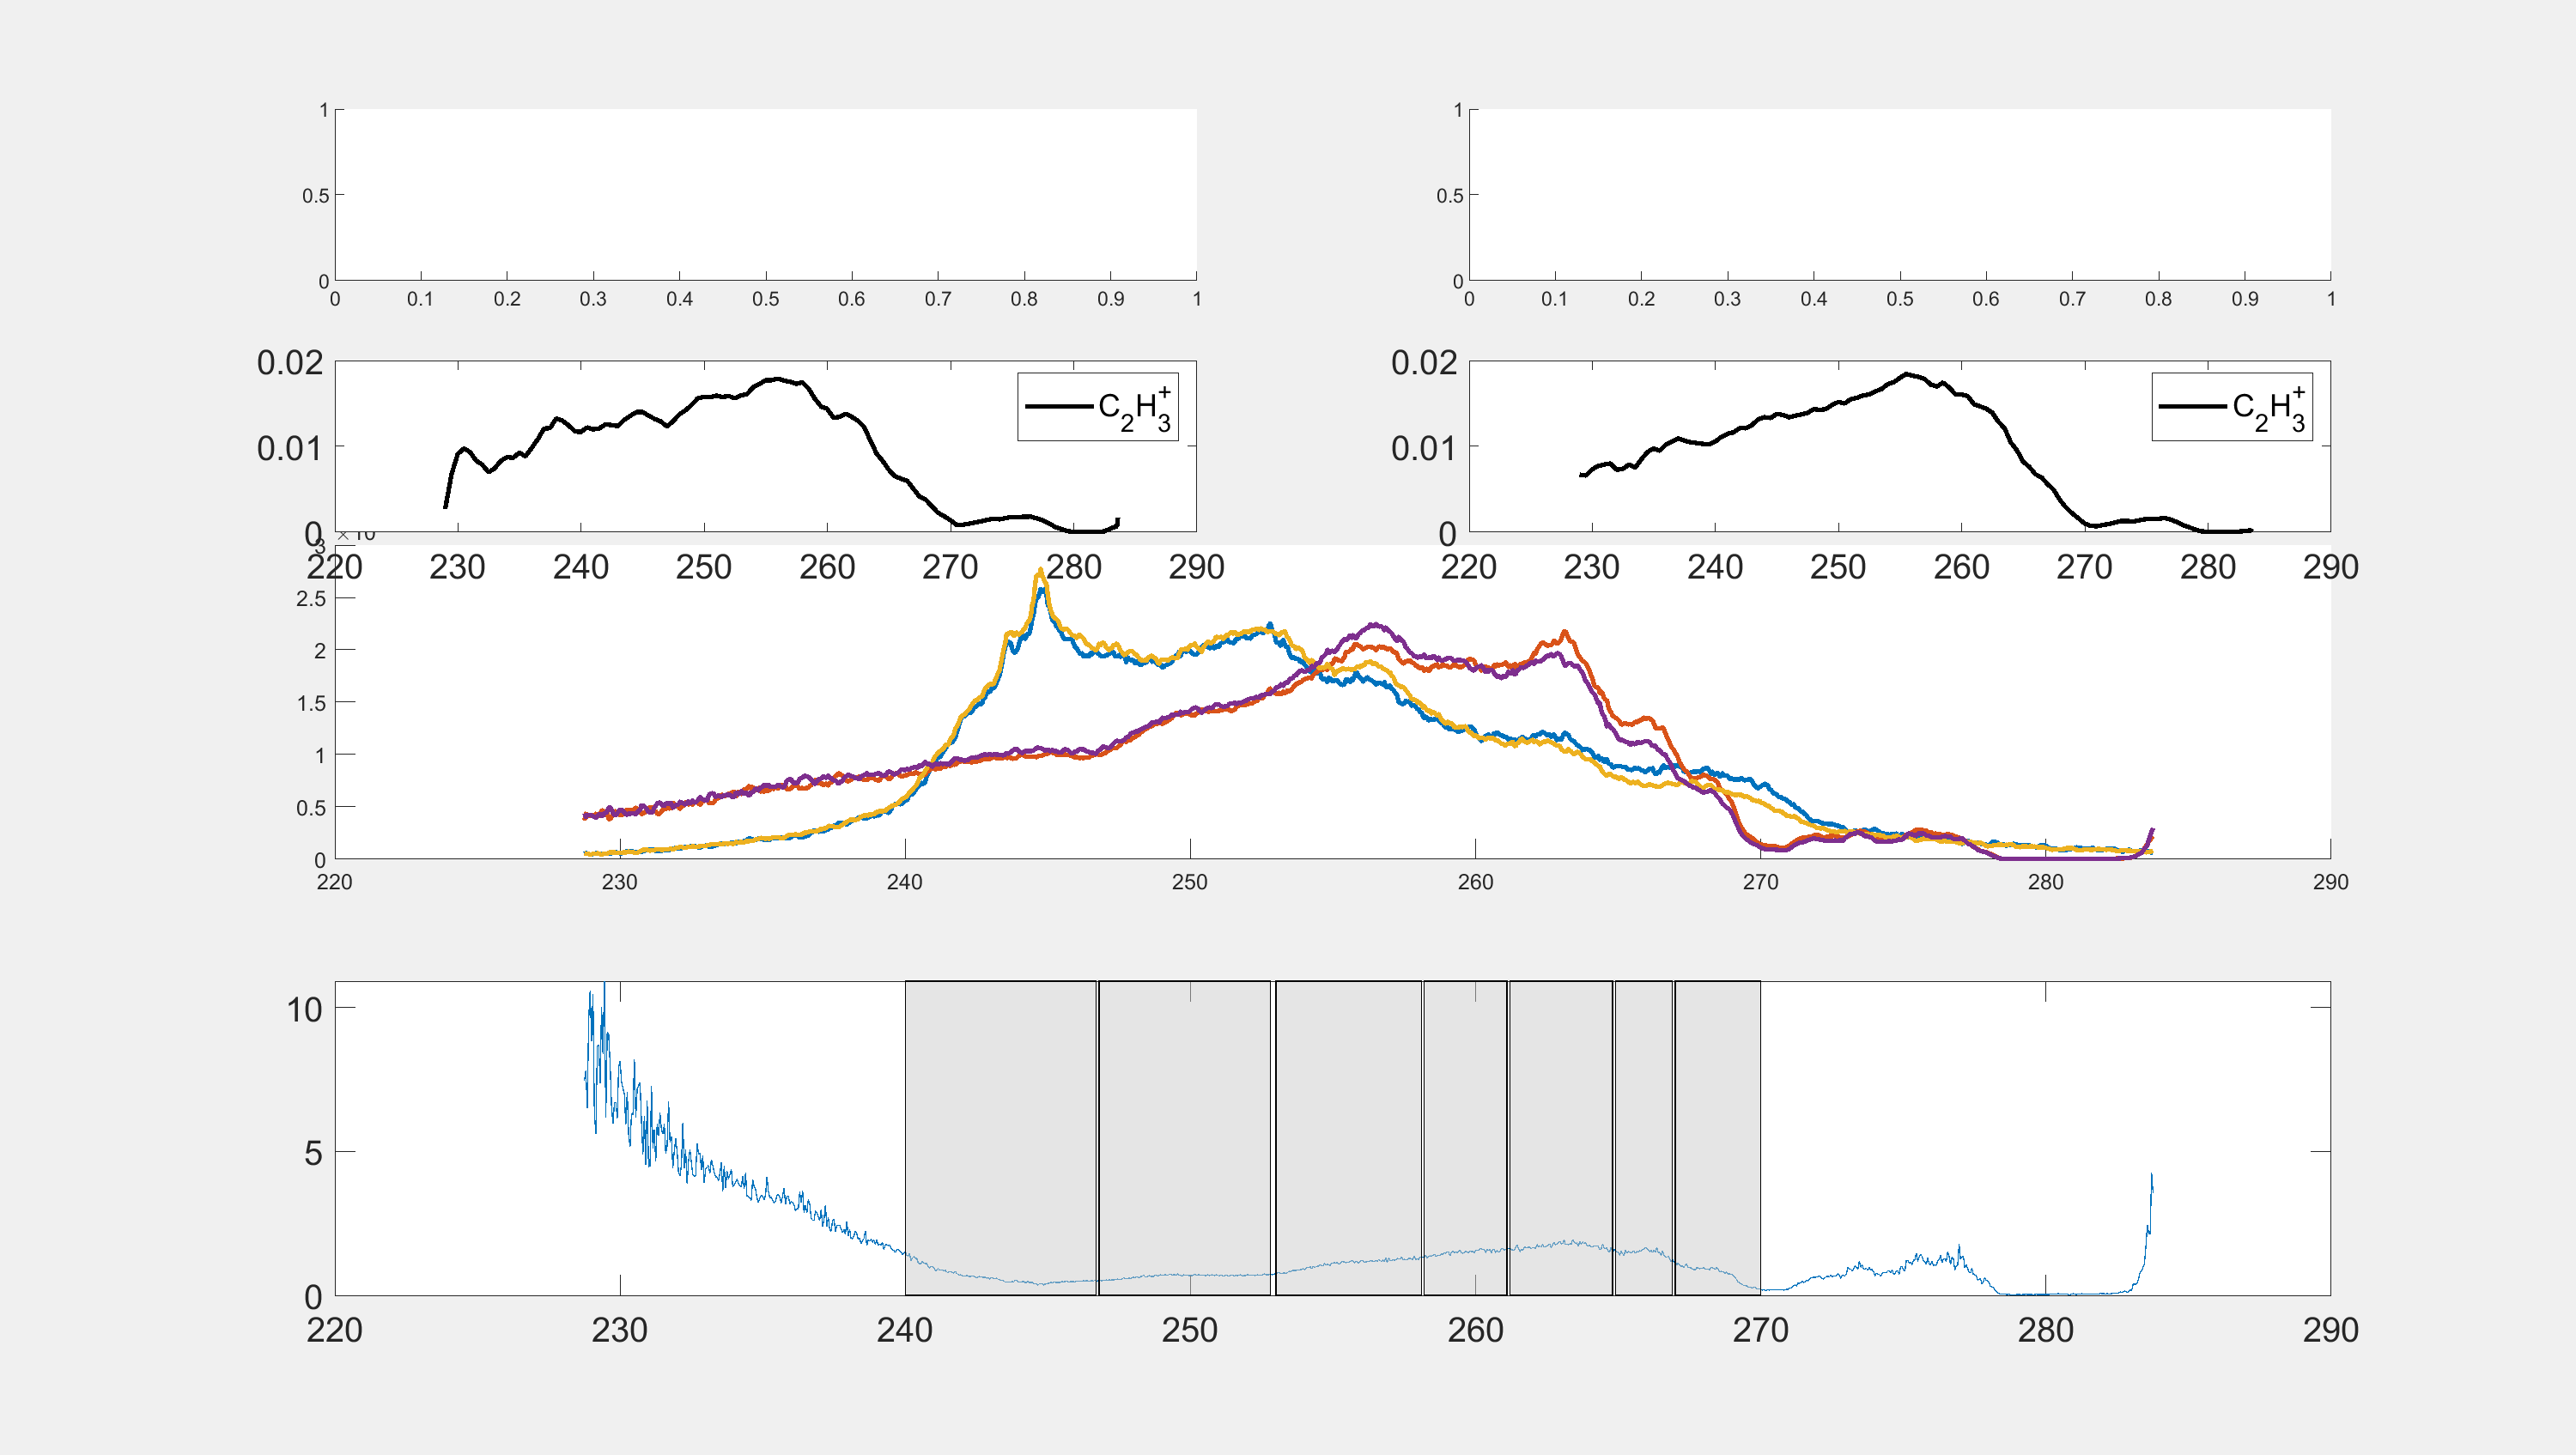

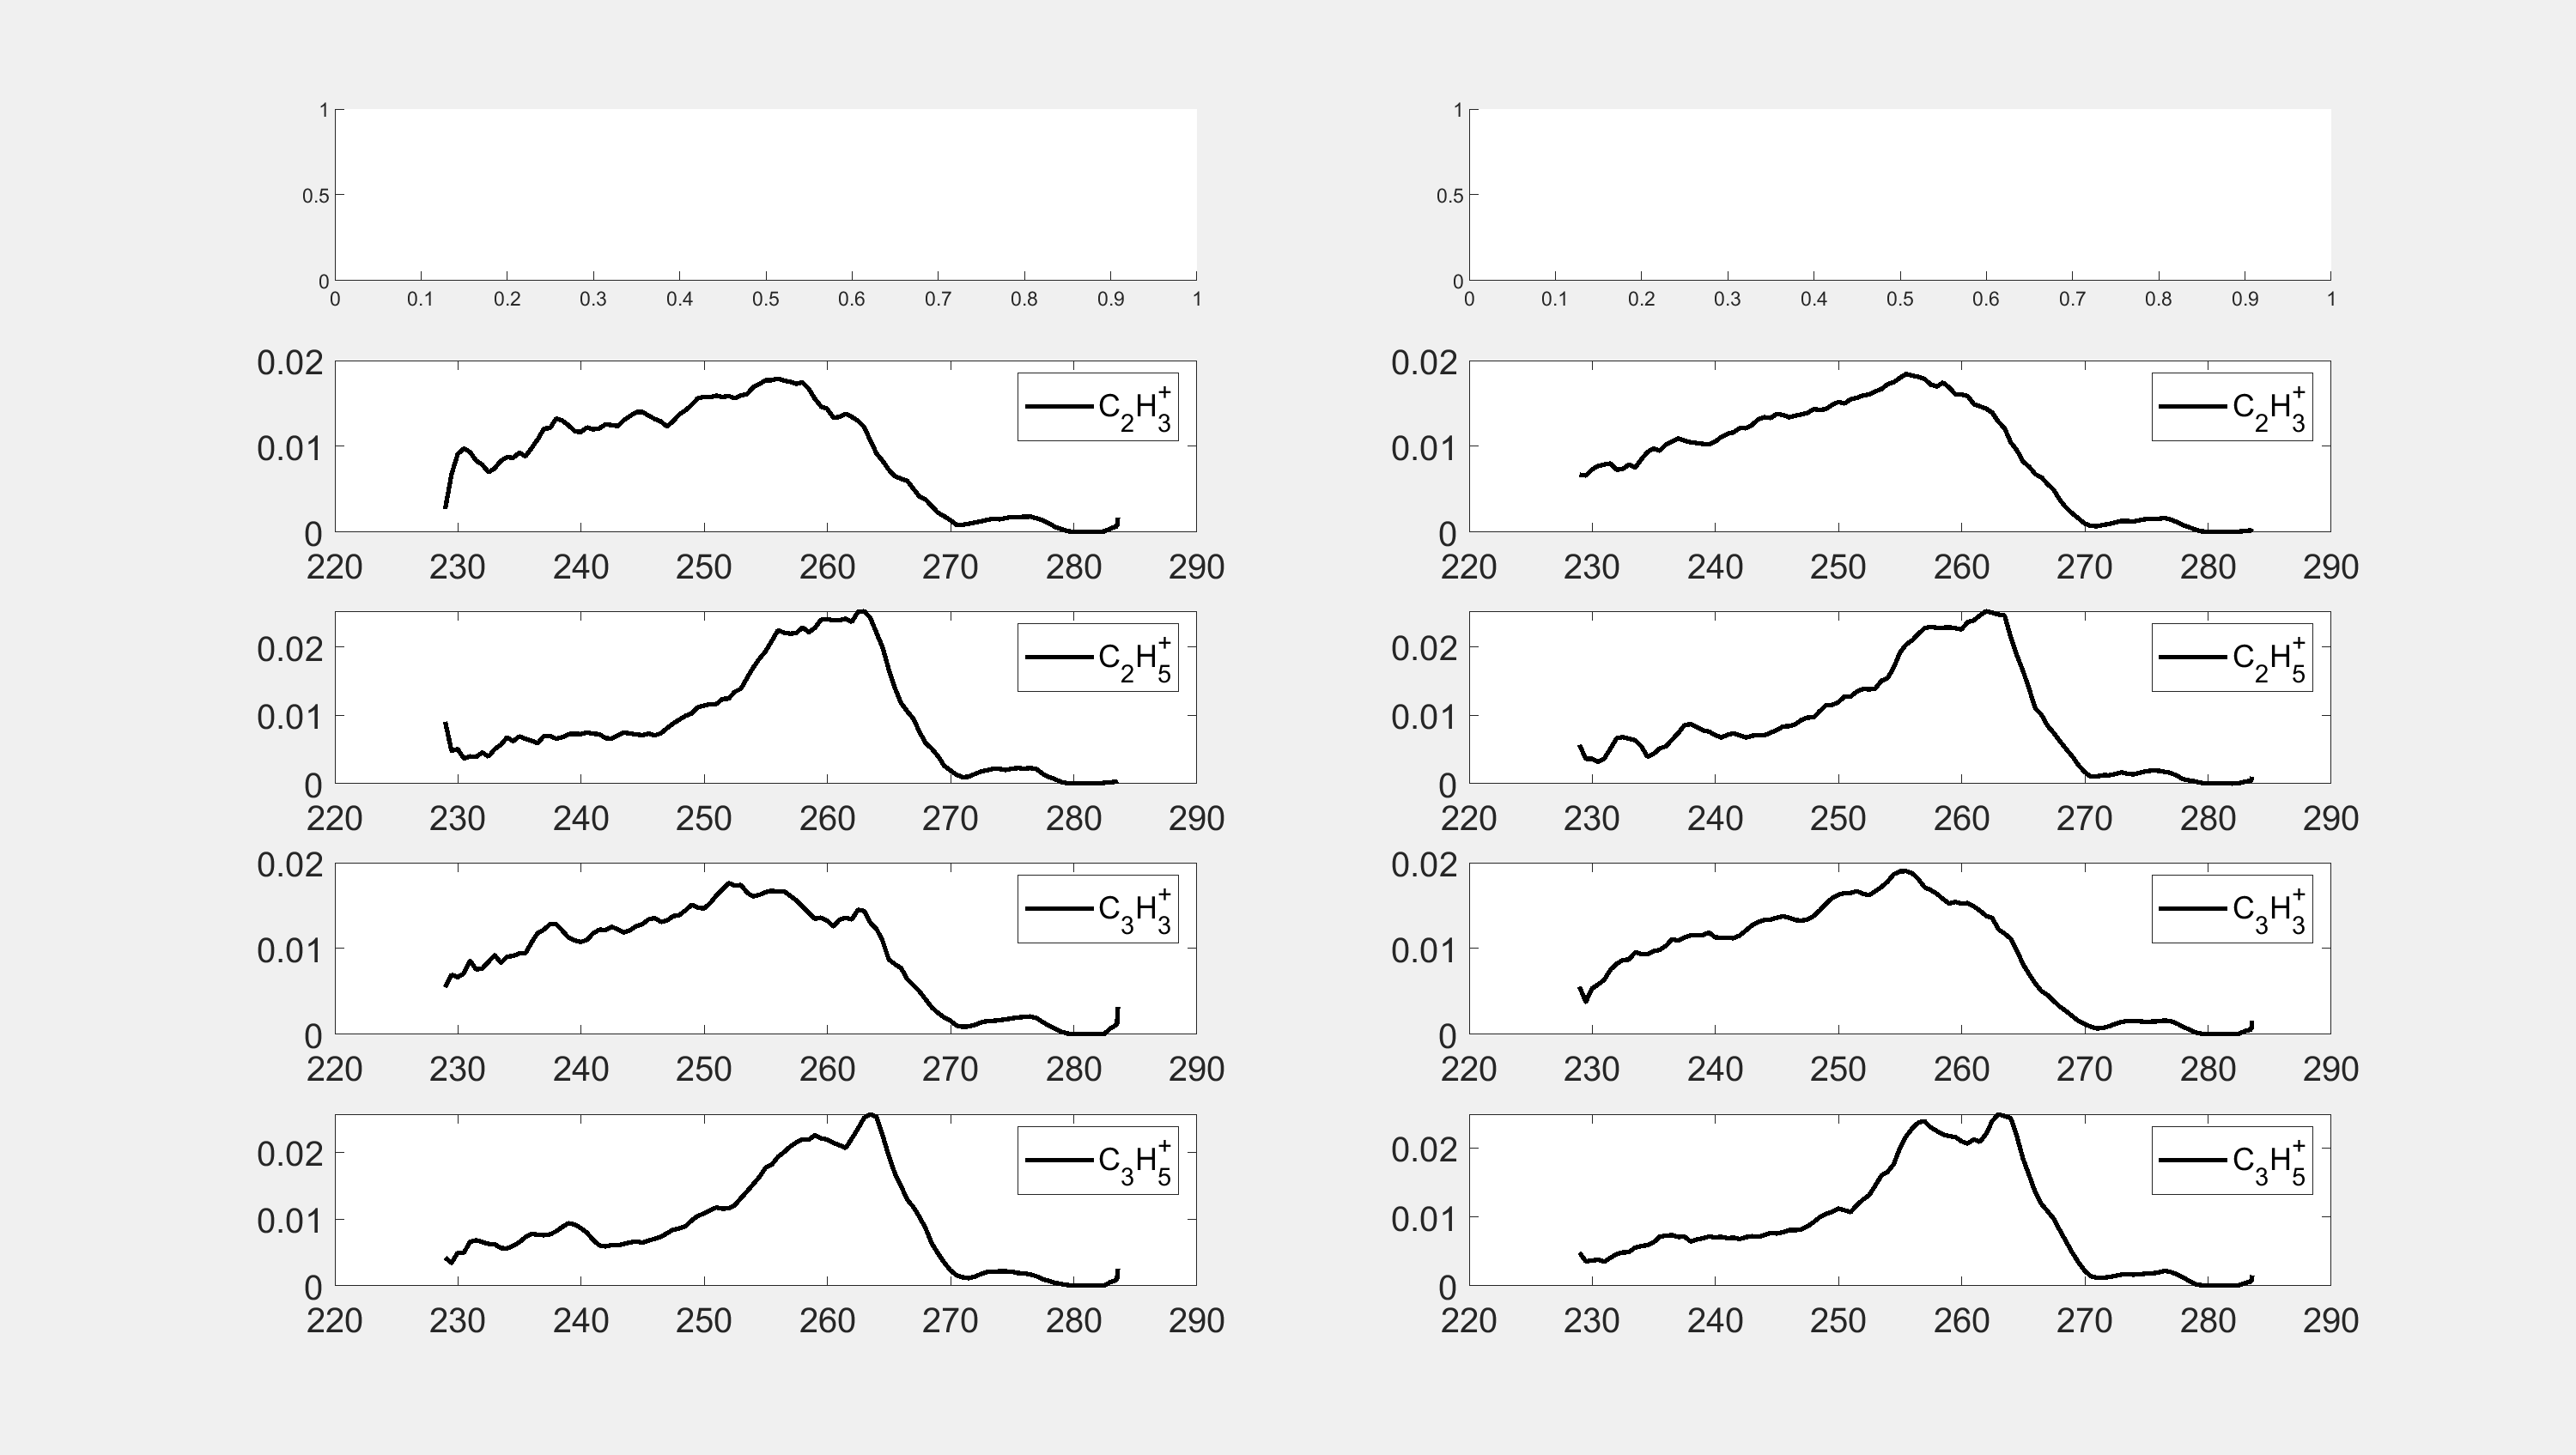

set(gca,'FontSize',15)
make_patch_es

for xx=1:length(m2q_val)
    C = floor(m2q_val(xx)/12);
    H = m2q_val(xx)-12*C;
    label =sprintf('C_%dH_{%d}^+', C,H);
    for i=1:length(S)
    subplot(length(m2q_val)+1,length(S),plt); 
    tof = convert.m2q_2_TOF(m2q_val(xx),mdata(i).conv.det2.m2q.factor,mdata(i).conv.det2.m2q.t0);
    [TetEI_x_tof1,Xcenters,Ycenters] = get_pepico(data_converted(i), data_stats(i),[tof-dtof;tof+dtof], epicea_2_scienta );     
    y1 =sum(TetEI_x_tof1, 2);
    energy_val = Xcenters;%Xedges(1:end-1) + diff(Xedges) / 2;
    hold on %
    plot(energy_val,smooth(y1./sum(y1)),'Color','k','DisplayName',label,'LineWidth', 2); 
    set(gca,'FontSize',15)
    legend 
    box on
    plt=plt+1;
%     make_patch_es
    end
end

% sgtitle(hv{i})


## PIPICO

for i=1:length(S)
    figure; 
    subplot(1,2,1)
    [Tet_tof2,Bincenters] = plot_pipico(data_converted(i), data_stats(i));
% %     [Tet_tof2] = plot_p_norm_p_norm(data_converted(i), data_stats(i),roi,m2q_1,m2q_2);
    title(hv{i})
    cm_magma=magma(50);
    colormap(cm_magma)
    axis tight
    xlim([3000 8000])
    ylim([3000 10000])
    daspect([1 1 1])
    box on
    colorbar
    caxis([0 1.5]) 
    caxis([0 2.25])

    roi_path='E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\roi_final_filt\';
    [xvalues, d] = get_counts_in_roi(roi_path, Tet_tof2, Bincenters );
    c =d;
    yvalues =xvalues;
    counts= sum(c,'all','omitnan');
    cdata = c.*100./counts;
    subplot(1,2,2)
    I = imagesc(flip(cdata)); 
    
    colormap(magma(50))%plot.myjet(100))
    % set(gca,'ColorScale','log')
    
    set(gca, 'XTick', 1:1:18, 'XTickLabel', xvalues)
    set(gca, 'YTick', 1:1:18, 'YTickLabel', flip(yvalues))
    axis tight
    xlim([0.5 8.5])
    daspect([1 2 1])
    colorbar
    A =flip(cdata);
    A = A(:,1:8);
    [R, C] = ndgrid(1:size(A,1), 1:size(A,2));
    R = R(:); C = C(:) - 1/4;
    %rows are Y values, columns are X values !
    vals = compose('%.1f',A(:));
    
    for k = 1:numel(vals)
      if isnan(str2num(vals{k}))
        vals{k} = '';
      end
    end
    text(C, R, vals, 'color', 'w','FontSize',15)
end